# Aquifer property estimation: Introduction

## Introduction

This example demonstrates how to detect recession events, and then estimate recession parameters *a* and *b* using the hybrid Pareto distribution-"point cloud" method (Cooper et al. 2023). Unlike the traditional point-cloud method, the key advantage of this method is that the Pareto distribution identifies "late-time" drainage behavior and provides an estimate of *b* for the late-time regime.

We use daily streamflow data measured in the Kuparuk River Basin on the North Slope of Alaska provided by the United States Geological Survey, recorded at streamflow gage 1596000. The data are included in the `data/` folder as a sample dataset with this toolbox, or can be downloaded from [https://waterdata.usgs.gov/monitoring-location/15896000.](https://waterdata.usgs.gov/monitoring-location/15896000.)

## Prepare data for recession analysis

Start with a clean workspace. 

clearvars
clc

Use tab-completion to set the argument to the `basinname` function.

sitename = baseflow.basinname('KUPARUK R NR DEADHORSE AK'); %#ok<*NASGU> 

Load streamflow data for the test basin into the workspace. In the sample dataset, the variable `T` is *time*, `Q` is *discharge*, and `R` is *rainfall*.

[T, Q, R] = baseflow.loadExampleData();

The minimum required information for baseflow recession analysis is a timeseries of streamflow. For aquifer property estimation, the surface area of the upstream aquifer (or catchment) $A$ is also needed. In addition, the geomorphological parameters drainage density $D_d$, effective stream channel length $L$, effective aquifer (or catchment) slope $\theta$, and saturated soil (or aquifer) thickness $D$ are needed in some cases. If an estimate of $D_d$ is unavailable, it will be set to the default value 0.8. 

Set the basin area and geomorphological parameters.

Dd = 0.8;            % drainage density 
A = 8.6545e9;        % basin area [m2]
L = A*Dd/1000;       % active stream length

## Set options for detecting and fitting recession events

In this example, we use default options for `getevents` and `fitevents`, but for `globalfit` we specify $A$, $D_d$, and $L$, and set the `isflat` parameter `true`, which indicates that slope is not included in the underlying theoretical solutions to the groundwater flow equation for this case. We set the `plotfits` parameter `true` to plot the fitted results. 

Set the algorithm options.

opts.getevents = baseflow.setopts('getevents');
opts.fitevents = baseflow.setopts('fitevents');
opts.globalfit = baseflow.setopts('globalfit', ...
   'drainagearea', A, 'drainagedensity', Dd, ...
   'streamlength', L, 'isflat', true, 'plotfits', true);

## Aquifer characterization workflow

The following steps demonstrate a typical workflow in aquifer characterization analysis. The steps consist of getting a list of recession events, fitting the recession events, and then estimating aquifer properties (recession parameters) including *a, b, *drainable porosity $\phi$, initial saturated thickness $D$, and hydraulic conducivity $k$.

### Step 1. Get events

EventData = baseflow.getevents(T, Q, R, opts.getevents);

### Step 2. Fit events

[EventFits, FitsTable] = baseflow.fitevents(EventData, opts.fitevents);

### Step 3. Fit recession parameters *a* and *b*

Pass the event discharge data $Q$ and recession rate $dQ/dt$ to `baseflow.fitab` with fitting method set to `nls` for "nonlinear least squares". Generate a point-cloud plot by setting `plotfit` to `true`. 

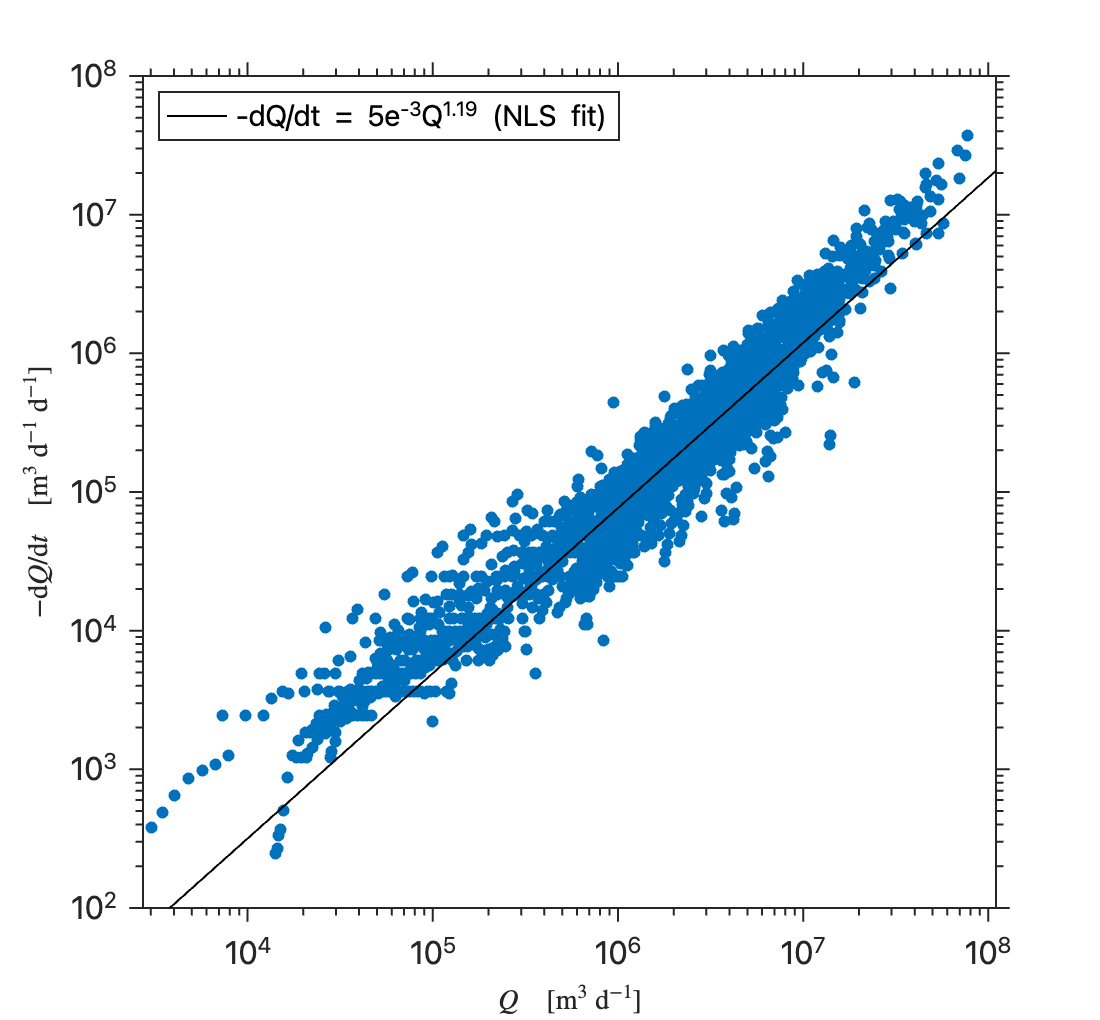

q = EventFits.q;
dqdt = EventFits.dqdt;
abfit = baseflow.fitab(q, dqdt, 'nls', 'plotfit', true);

ahat = abfit.a;
bhat = abfit.b;

### Step 4. Estimate aquifer properties

Pass the event discharge data $Q$ and recession rate $dQ/dt$, and the estimated *a* and *b* values to the `aquiferprops` function to estimate the remaining aquifer properties. In this example, we use the "BS04" method which designates the "Boussinesq, 1904" non-linear late-time solution. 

Props = baseflow.aquiferprops(q, dqdt, ahat, bhat, 'BS04', 0.033, A, L);

 The aquifer properties returned in the `Props` struct include the following:

k = hydraulic conductivity in units cm s-1

D = saturated aquifer thickness in units m

Q0 = critical value of baseflow in units m3 s-1

a1 = early-time recession constant in discharge equation -dQ/dt = aQ^b

b1 = early-time recession constant in discharge equation -dQ/dt = aQ^b

a2 = late-time recession constant in discharge equation -dQ/dt = aQ^b

b2 = late-time recession constant in discharge equation -dQ/dt = aQ^b

## Aquifer property estimation in detail

When estimating aquifer properties using baseflow recession analysis, keep in mind that the procedure involves two equations with known parameters. Therefore, we can estimate two unknowns. The two equations are the early-time solution to the groundwater flow equation, and the late-time solution. 

The parameters *a* and *b* in the late-time solution are estimated by curve fitting individual events using `baseflow.fitevents` and then estimating a population average. The parameter *b* in the early-time solution has a known theoretical value of 3, and the parameter *a* in the early-time solution is estimated by fitting a line of slope *b*=3 through the early-time point cloud. 

The unknown aquifer properties include the initial saturated aquifer thickness *D*, the lateral saturated hydraulic conductivity *k*, the drainable porosity $\phi$, and the "critical baseflow" $Q_0$. The critical baseflow marks the transition from early-time to late-time discharge. At that point, the early-time and late-time solutions are equivalent, which provides a method to solve for $Q_0$, leaving three remaining unknowns.

Once the early-time and late-time *a* and *b* values are known, there are two options for estimating the unknown aquifer properties provided by the baseflow toolbox. 

The first option uses known or assumed values for $\phi$, which are tabulated in the literature for various soil types, and then estimates *D,* *k,* and $Q_0$ using the early-time and late-time parameters *a* and *b*. This approach has been used to estimate changes in the groundwater layer thickness over time (Brutsaert, 2007), and to parameterize rainfall-runoff models (Troch et al. 1993). This approach is implemented in the `aquiferprops` function.

The second option is to use known or assumed values for *D*, and then compute $\phi$ and *k*. This option has been used to estimate changes in the groundwater layer thickness over time for systems where a reference measurement of *D* is available (Cooper et al. 2023). The reason one might choose this method is because the quality of the trend fit is highly dependent on the a-priori estimate of *D*, and one only needs a reference *D* around which the trend is linearized. This topic is beyond the scope of this tutorial; see Cooper et al. 2023 for more detail.

In both cases, the critical baseflow value $Q_0$ is the intersection of the early- and late-time curves on the point cloud. This value can be used for *baseflow* *separation*, which is a classical method in hydrology that separates "fast" storm-flow runoff from "slow" baseflow (groundwater) runoff.

The second method is demonstrated using the `cloudphi` method, which uses the point cloud to estimate $\phi$ from the intersection of the early-time and late-time curves. Unlike the `aquiferprops` function, we use an estimate of the saturated aquifer thickness *D*=0.5 m, which was obtained from field measurements of the saturated soil layer in the study basin. We designate 'brutsaert' for the method used to place the late-time line on the point cloud, which places the line such that ~5% of the *Q* and *-dQ/dt* values fall below it. 

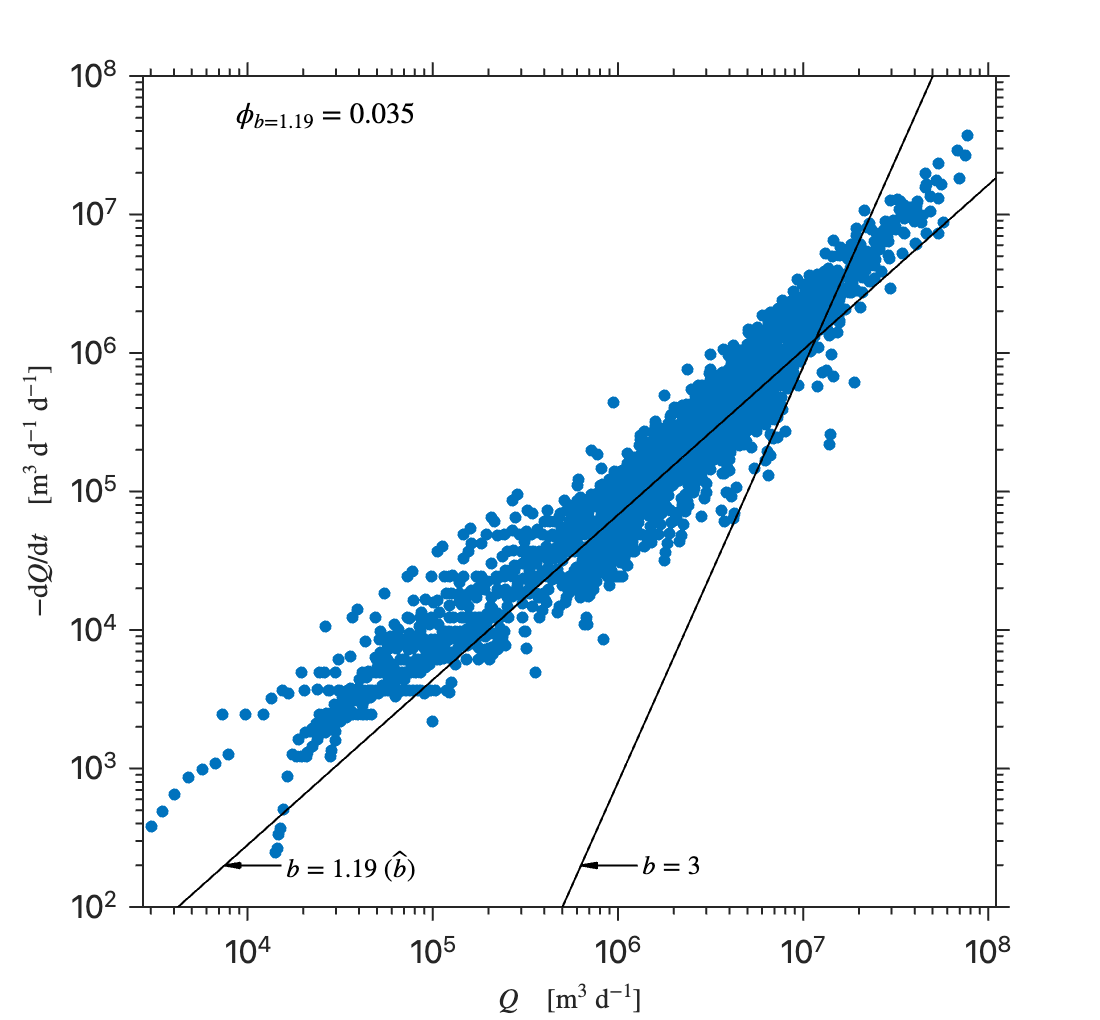

D = 0.5; 
phi = baseflow.cloudphi(q,dqdt,bhat,A,D,L,'brutsaert','lateqtls',...
   opts.globalfit.lateqtls,'earlyqtls',opts.globalfit.earlyqtls);

The value obtained for $\phi$ is ~0.03-0.04, similar to values obtained in other baseflow recession analysis studies. If this value is used in the `aquiferprops` function instead of the assumed value 0.01, we obtain different estimates of *k* and *D*.

Props = baseflow.aquiferprops(q, dqdt, ahat, bhat, 'RS05', phi, ...
   A, L, 'D', 0.5);

Props.D

ans = 0.7550

Props.k

ans = 1.2722

Typically, values for *k* obtained from baseflow recession analysis applied to streamflow records for catchments are 1-2 orders of magnitude larger than expected from laboratory measurements. The reason is because the theory is applicable to a single uniform aquifer discharging groundwater laterally. In reality, catchment outflow includes macropore and other non-diffusive flow that is much faster than diffusive groundwater flow.

Similarly, estimates of drainable porosity are often one order of magnitude lower than would be expected from laboratory measurements. One reason is because the catchment area *A* used in this and most similar analyses is the surface area of the catchment, but theoretically this value should be the *aquifer* contributing area, which is likely smaller than the catchment surface area. A second plausible reason is that the aquifer does not fully drain in reality, which is the case in laboratory measurements, meaning the drainable porosity estimated with baseflow recession analysis is only sampling a small portion of the aquifer.